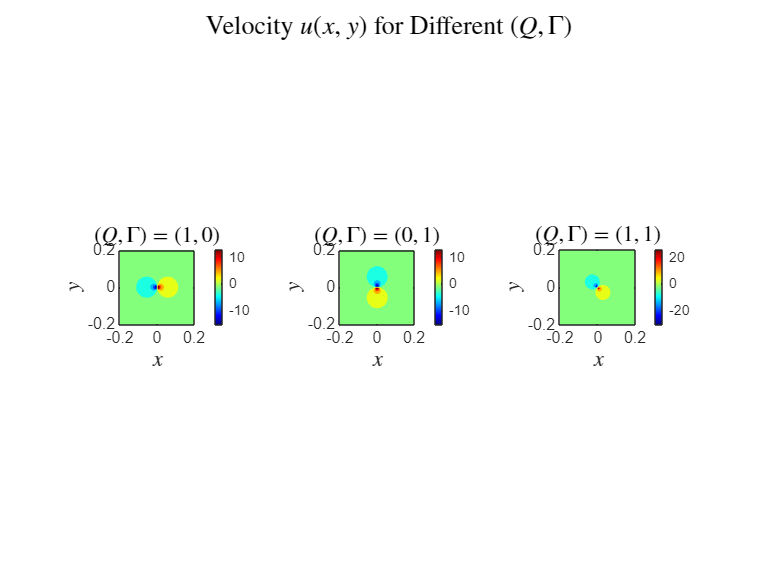

% Part (f): Plotting Velocity Component u(x,y) for Different (Q, Gamma) Pairs

% Clear workspace and close all figures
clear; close all; clc;

% Define the range for x and y
x = linspace(-0.2, 0.2, 40);
y = linspace(-0.2, 0.2, 40);
[X, Y] = meshgrid(x, y);

% Compute the denominator (x^2 + y^2)
denominator = X.^2 + Y.^2;

% Avoid division by zero by setting a minimum value
epsilon = 1e-6;
denominator(denominator < epsilon) = epsilon;

% Define the (Q, Gamma) pairs
cases = {
    struct('Q', 1, 'Gamma', 0, 'Title', '$(Q, \Gamma)=  (1, 0) $'),
    struct('Q', 0, 'Gamma', 1, 'Title', '$(Q, \Gamma) = (0, 1) $'),
    struct('Q', 1, 'Gamma', 1, 'Title', '$(Q, \Gamma) = (1, 1) $')
};

% Initialize figure
figure;

% Loop through each case and plot u(x,y)
for i = 1:length(cases)
    Q = cases{i}.Q;
    Gamma = cases{i}.Gamma;
    titleStr = cases{i}.Title;
    
    % Compute u(x,y) based on the given (Q, Gamma)
    U = (Q .* X - Gamma .* Y) ./ (2*pi .* denominator);
    
    % Plot using contourf for better visualization
    subplot(1, 3, i); % Create a subplot for each case
    contourf(X, Y, U, 10, 'LineColor', 'none'); % 50 contour levels for smooth coloring
    colorbar; % Display color scale
    title(titleStr, 'Interpreter', 'latex', 'FontSize', 12);
    xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12);
    axis equal tight; % Equal scaling for x and y axes
    colormap jet; % Use the 'jet' colormap
end

% Enhance layout
sgtitle('Velocity $u(x, y)$ for Different $(Q, \Gamma)$ ', 'Interpreter', 'latex', 'FontSize', 14);